# **Homework 2 - Calcolo Numerico Francesco Calcopietro Matr. 0124002090**

Come prima operazione di questo homework si caricano i dati definiti in precedenza: la foto scelta A e i vettori delle coordinate x e y dei punti selezionati sulla foto. 

load DatiHW2FC.mat;

**1.Visualizzare nella stessa figura la foto dell'oggetto e successivamente i 50 punti  evidenziati con un asterisco rosso sul contorno. Le componenti dei vettori **`x`**  e **`y`**  possono essere scalate, per es. dividendole per 1000, poi devono essere centrate nel baricentro (centroide della figura) e infine devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che **`x`** e **`y`** siano i vettori delle coordinate dei vertici di un poligono (chiuso).**

Si visualizza la foto scelta e i punti selezionati con un semplice plot.  

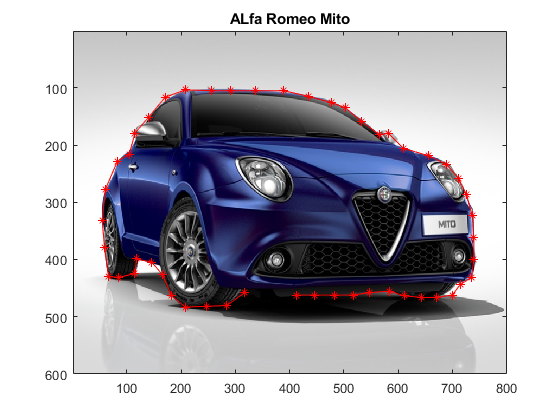

format long
figure(1)
image(A);
axis on 
hold on
title('ALfa Romeo Mito')
plot(x,y,"-*", "color",'red')
hold off

Si definiscono le coordinate del centroide, rispettivamente la media delle ascisse e delle ordinate dei punti selezionati sulla foto. Fatto ciò, si definiscono le nuove coordinate dell'intera immagine, questa volta centrata nel baricentro, andando a sottrarre ai vettori x e y, xc e yc. Si effettua un nuovo plot del poligono chiuso creato, centrato proprio nel baricentro. 

xc=mean(x)

xc =      3.992329650092080e+02


yc=mean(y)

yc =      3.194532710280374e+02


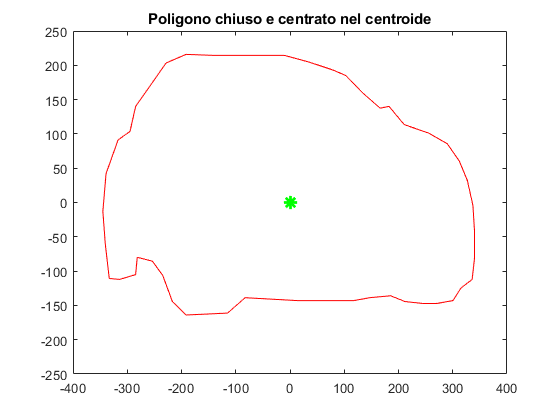

xcentrati=x-xc;
ycentrati=-(y-yc);                    %si utilizza un '-' per visualizzare l'immagine in maniera corretta e non capovolta
xcentrati=[xcentrati;xcentrati(1)];
ycentrati=[ycentrati;ycentrati(1)];
plot(xcentrati,ycentrati,'r')
hold on
plot(0, 0, 'g*', "MarkerSize", 10, "LineWidth", 2);
title('Poligono chiuso e centrato nel centroide')
axis([-400 400 -250 250]);
hold off

**2.Usando i vertici del poligono ottenuti in 1, costruire **`miafotoS`**, cioè la curva parametrica, basata sulle spline cubiche interpolanti, che interpola tali punti. Usare le spline cubiche con derivata prima fissata negli estremi (scegliere un valore appropriato della derivata per entambe le spline). Visualizzare sia il grafico della spline che interpola le ascisse dei punti, sia il grafico della spline che interpola le ordinate dei punti, sia  **`miafotoS `** indicando in blu i punti (per tutti e tre i grafici, usare una griglia fitta di 500 punti).**

Tale traccia chiede di risolvere un problema di interpolazione attraverso spline cubiche. Siccome si ha l'obiettivo di definire una curva parametrica, cioè dipendente da un parametro, si definisce quest'utlimo per poi usfruire delle ascisse e delle ordinate dei punti del poligono iniziale, i quali saranno funzioni del parametro scelto. Si sceglie come valore della derivata agli estremi 0, in quanto il primo e l'ultimo punto scelti sul poligono si trovano grosso modo sulla stessa quota.

l=1:length(xcentrati)                         %definizione del parametro

l =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


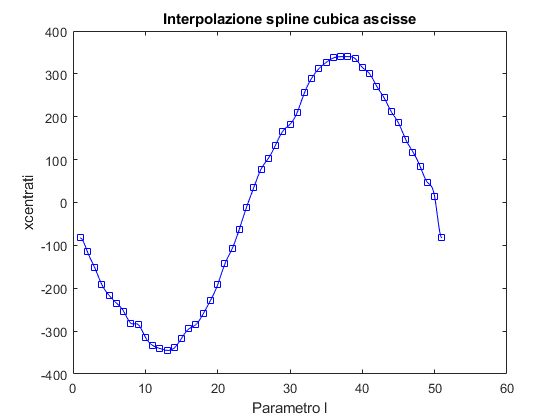

xx=linspace(l(1),l(end),500);                   %definizione della griglia di 500 punti
ascisseSplineC=spline(l,[0 xcentrati' 0],xx);   %interpolazione delle ascisse in funzione del parametro
ordinateSplineC=spline(l,[0 ycentrati' 0],xx);  %interpolazione delle ordinate in funzione del parametro
plot(l,xcentrati,'bs',xx,ascisseSplineC,'b')
title('Interpolazione spline cubica ascisse')
xlabel("Parametro l")
ylabel("xcentrati")

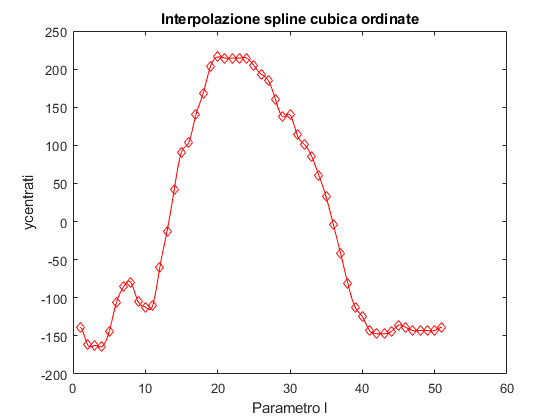

plot(l,ycentrati,'rd',xx,ordinateSplineC,'r');
title('Interpolazione spline cubica ordinate')
xlabel("Parametro l")
ylabel("ycentrati")

A questo punto si prendono i risultati dell'interpolazione sulla griglia fitta e si costruisce la curva parametrica miafotoS. Si nota come, mediante la definizione della derivata agli estremi, si rende più liscio il contorno dell'oggetto considerato.

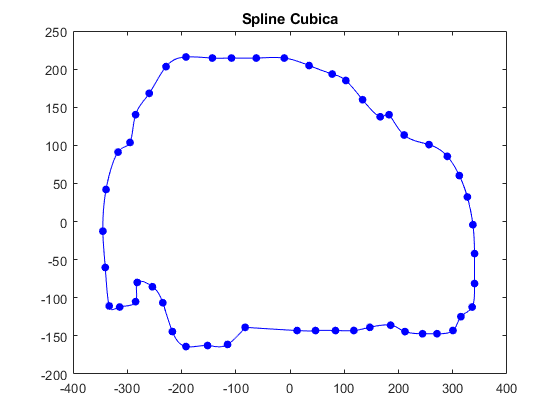

miafotoS=[ascisseSplineC;ordinateSplineC];
plot(xcentrati,ycentrati,'b.',ascisseSplineC,ordinateSplineC,'b','markersize',20,'LineWidth',0.5)
title('Spline Cubica')

**3.Ripetere tutto quanto richiesto in 2.  per costruire **`miafotoC`**, ovvero la curva parametrica basata sulle cubiche di Hermite. Calcolare la norma infinito del vettore (di 500 componenti) che ha per i-sima componente la distanza tra l' i-simo punto di **`miafotoS `**e l' i-simo punto di **`miafotoC`**. **

Come detto già dalla traccia, si ripetono tutte le azioni fatte per la sezione precedente; l'unica cosa che cambia è il richiamo alla funzione *pchip *usata proprio per la costruzione di una cubica interpolante di Hermite. Essa avrà sempre gli stessi argomenti in ingresso.

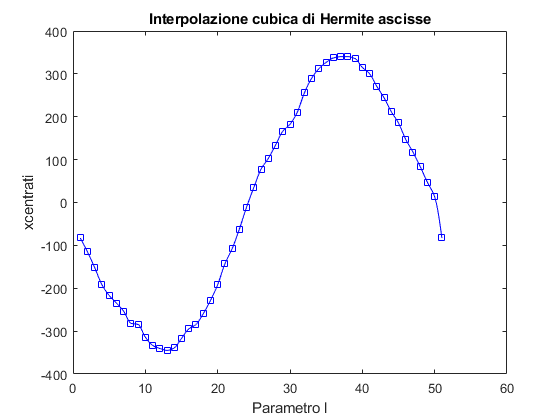

l=1:length(xcentrati);
xx=linspace(l(1),l(end),500);
ascisseSplineH=pchip(l,xcentrati,xx);
ordinateSplineH=pchip(l,ycentrati,xx);
plot(l,xcentrati,'bs',xx,ascisseSplineH,'b')
title('Interpolazione cubica di Hermite ascisse')
xlabel("Parametro l")
ylabel("xcentrati")

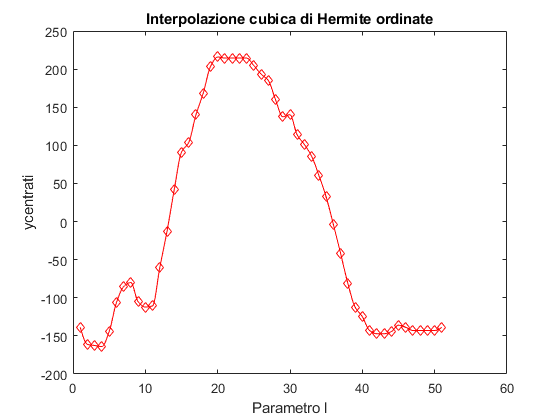

plot(l,ycentrati,'rd',xx,ordinateSplineH,'r');
title('Interpolazione cubica di Hermite ordinate')
xlabel("Parametro l")
ylabel("ycentrati")

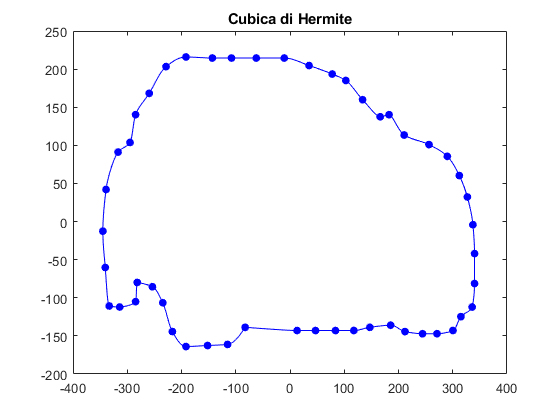

miafotoC=[ascisseSplineH; ordinateSplineH];
plot(xcentrati,ycentrati,'b.',ascisseSplineH,ordinateSplineH,'b','markersize',20,'LineWidth',0.5)
title('Cubica di Hermite')

Si nota come tale rappresentazione sia leggermente più accurata della precedente grazie alla qualità dello shape preserving delle cubiche di Hermite.

Attraverso la formula classica per il calcolo delle distanze tra i vari punti della spline cubica e della cubica di Hermite si costruisce il vettore che contiene proprio queste distanze. Di tale vettore si calcola la norma infinito che restituisce la più grande distanza tra tali punti.

vettoreDistanza=sqrt((ascisseSplineC-ascisseSplineH).^2 + (ordinateSplineC-ordinateSplineH).^2);
norm(vettoreDistanza,inf)

ans =   22.334388627394240


**4. Considerare il poligono di 500 vertici costituito dai valori della curva parametrica miafotoS. Visualizzare in rosso tale poligono, usando il comando fill. Calcolare e visualizzare il perimetro e l'area di questo poligono usando le function LunghezzaPoligonale  e   AreaPoligono sviluppate nell'Esercitazione ONLINE8.**

Il comando fill permette di riempire, in questo caso di rosso, tutta l'area del poligono costruito.

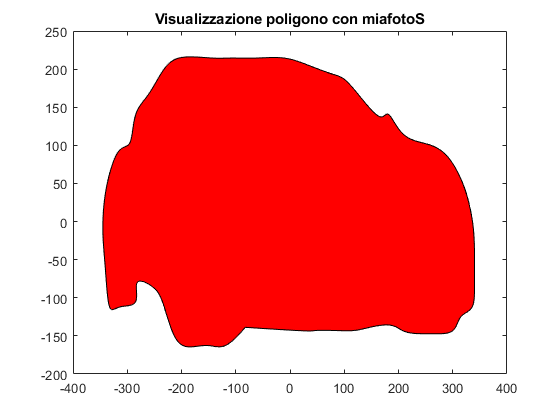

fill(ascisseSplineC,ordinateSplineC,'r')
title('Visualizzazione poligono con miafotoS')

Di seguito il calcolo del perimetro e dell'area del poligono costituito dai valori della curva parametrica miafotoS. 

perimetro1=Lunghezza(ascisseSplineC,ordinateSplineC)

perimetro1 =      1.891872811377452e+03


area1=AreaPoligono(ascisseSplineC,ordinateSplineC)

area1 =      2.044473647822203e+05


**5. Ripetere tutto quanto richiesto in 4. per la curva parametrica **`miafotoC`**. Calcolare e visualizzare la differenza tra il perimetro di **`miafotoS e miafotoC`**   e la differenza tra l'area di  **`miafotoS`**  e  **`miafotoC.`

Si ripetono gli stessi e identici passi della sezione 4. 

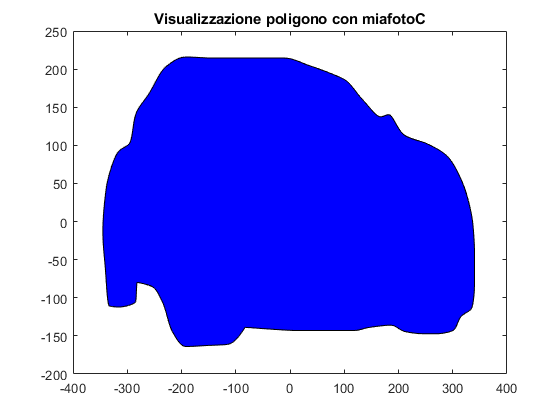

fill(ascisseSplineH,ordinateSplineH,'b')
title('Visualizzazione poligono con miafotoC')

perimetro2=Lunghezza(ascisseSplineH,ordinateSplineH)

perimetro2 =      1.886273856988013e+03


area2=AreaPoligono(ascisseSplineH,ordinateSplineH)

area2 =      2.044554822562903e+05


Ciò che si osserva è che, siccome ci sono delle differenze, sottili ma ci sono, tra la spline cubica e la cubica di Hermite, ci sono delle differenze anche in ambito di perimetro e area. Più precisamente il perimetro della spline cubica è più grande del perimetro della spline di Hermite; per quanto riguarda l'area è al contrario.

differenzaP=perimetro1-perimetro2

differenzaP =    5.598954389438859


differenzaA=area1-area2

differenzaA =   -8.117474069935270


**6. Costruire la matrice D delle distanze dei 51 punti  ottenuti al termine della domanda 1. cioè la matrice quadrata di ordine 51 il cui elemento (i,j) è la distanza tra  il punto i e il punto j . Visualizzare il blocco di D che coinvolge le distanze tra i primi 8 punti.**

Si costruisce la matrice delle distanze elemento per elemento con un doppio ciclo for.

D = zeros(length(xcentrati));
for i=1:51
    for j=i+1:51
        D(i,j)=sqrt(((xcentrati(j)-xcentrati(i)).^2)+((ycentrati(j)-ycentrati(i)).^2));
    end
end

Di seguito la visualizzazione della matrice D1, la quale è caratterizzata dalle distanze tra i primi 8 punti della matrice D.

D1=D(1:8,1:8)

D1 = 	1.0e+02 *

                   0   0.394166507458982   0.732312408160096   1.119060166342294   1.341871966921458   1.551371432429196   1.790123759397669   2.074268794688653
                   0                   0   0.368590809625600   0.766627049083309   1.030399584120526   1.312648056897047   1.578292618299011   1.852767715433804
                   0                   0                   0   0.398036997989584   0.673380402935878   0.997566494600192   1.275895028045276   1.537860099493376
                   0                   0                   0                   0   0.318196578341166   0.716173191307550   0.999596249350465   1.230921033121114
                   0                   0                   0                   0                   0   0.417758859333493   0.694500174570339   0.914370186492524
                   0                   0                   0                   0                   0                   0   0.284431044744595   0.541493088467104
                 

**7. Usando la matrice delle distanze D ricavata in 6., determinare la distanza tra i due punti più lontani del bordo dell'oggetto (ovvero il diametro della nube di punti), visualizzare tale distanza e visualizzare una figura con il contorno dell'oggetto e il segmento (in rosso) che unisce i due punti più lontani.**

Si calcola la massima distanza che c'è tra i punti nel vettore D. Si preleva la posizione di tale distanza massima. Mediante la funzione *ind2sub* si 'traduce' la posizione appena ottenuta negli indici dei punti che sono più distanti nel poligono. 

[max_val,pos_idx]=max(D(:))

max_val =      6.921659113896047e+02


pos_idx =         1952


[X, Y]=ind2sub(51,pos_idx)

X =     14


Y =     39


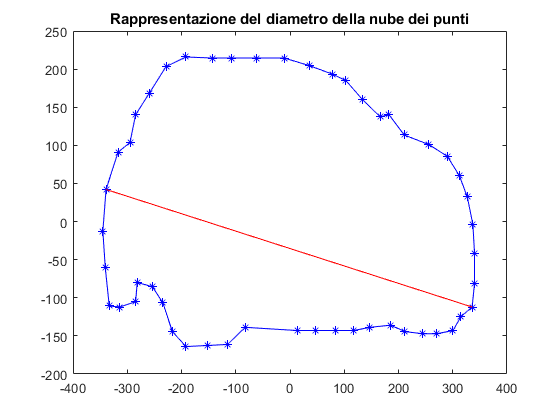


plot(xcentrati,ycentrati,"-*", "color",'blu')
hold on
plot([xcentrati(Y) xcentrati(X)],[ycentrati(Y) ycentrati(X)],'-r')
title('Rappresentazione del diametro della nube dei punti')
hold off

**8. Fissare un angolo **`teta`** a caso (usare opportunamente **`rand`**) tra 10 e 80 gradi e fare ruotare in verso orario **`miafotoS `**di tale  angolo e in verso antiorario **`miafotoC`**. Visualizzare nella stessa figura  **`miafotoS `**e **`miafotoS `**ruotata  e poi in un'altra figura  **`miafotoC `** e  **`miafotoC `**ruotata.**

Si estrae un angolo a caso tra 10 e 80 con la funzione *rand,* si definisce la matrice di rotazione R prima in senso orario e poi R' in senso antiorario. Per effettuare la rotazione si effettua il prodotto tra la matrice di rotazione e, prima miafotoS e poi miafotoC.

a=10;
b=80;
teta=floor(a+(b-a)*rand(1,1))

teta =     67


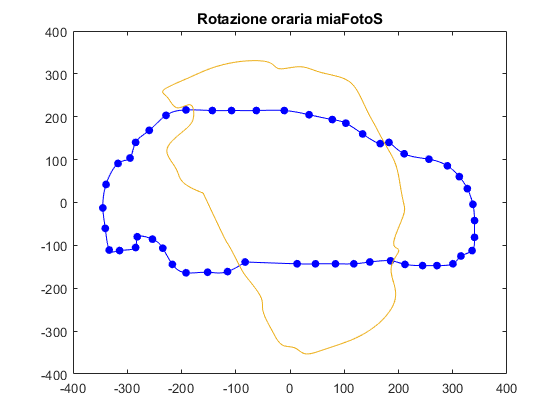

R=[cosd(teta) sind(teta); -sind(teta) cosd(teta)];
miafotoS1= R*miafotoS;
plot(xcentrati,ycentrati,'b.',ascisseSplineC,ordinateSplineC,'b','markersize',20,'LineWidth',0.5)
hold on
plot(miafotoS1(1,:),miafotoS1(2,:))
title('Rotazione oraria miaFotoS')
hold off

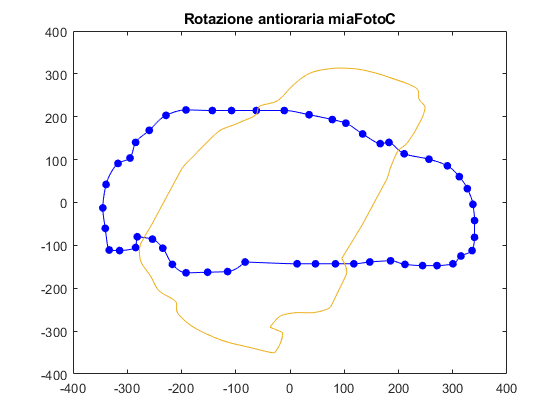

miafotoC=[ascisseSplineH;ordinateSplineH];
miafotoC1= R'* miafotoC;
plot(xcentrati,ycentrati,'b.',ascisseSplineH,ordinateSplineH,'b','markersize',20,'LineWidth',0.5)
hold on
plot(miafotoC1(1,:),miafotoC1(2,:))
title('Rotazione antioraria miaFotoC')
hold off

**9. Usando i vertici del poligono ottenuti in 1, costruire **`miafotoAppr5`**, cioè la curva parametrica, basata sull'approssimazione nel senso dei minimi quadrati con polinomi di grado 5., ottenuta approssimando separatamente le ascisse e le ordinate di tali punti. Visualizzare sia il grafico del polinomio che approssima nel senso MQ le ascisse dei punti, sia il grafico del polinomio che approssima nel senso MQ  le ordinate dei punti, sia **`miafotoAppr5`**, indicando in blu i punti (per tutti e tre i grafici, usare una griglia fitta di 500 punti).**

Si vuole quindi risolvere un problema di approssimazione, cioè costruire una curva parametrica, quindi dipendente da un parametro, che vada ad approssimare prima le ascisse e poi le ordinate dei punti del poligono definito nella sezione 1. La costruzione della curva è effettuata con *polyfit,*il quale avrà in ingresso l'insieme dei nodi, le quote e il grado della curva da costruire, in questo caso 5. Fatto questo ci sarà *polyval *che andrà a valutare il polinomio ottennuto su una griglia di 500 punti.

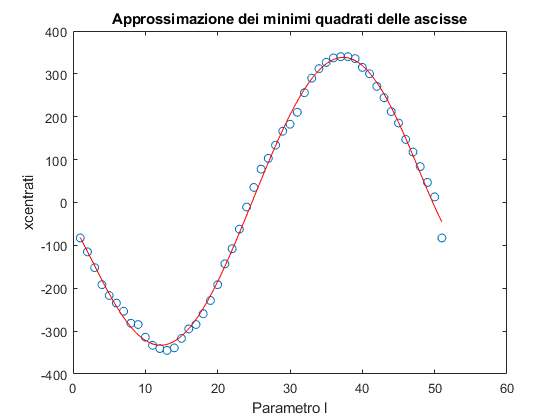

l=1:length(xcentrati);
a=polyfit(l,xcentrati,5);
polinomioA=polyval(a,xx);
plot(l,xcentrati,'o',xx,polinomioA,'r')
title('Approssimazione dei minimi quadrati delle ascisse')
xlabel("Parametro l")
ylabel("xcentrati")

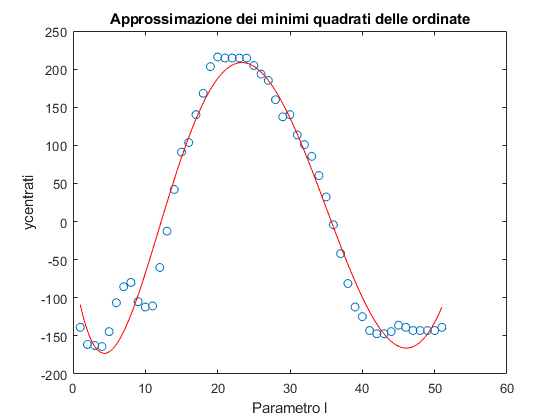

a=polyfit(l,ycentrati,5);
polinomioB=polyval(a,xx);
plot(l,ycentrati,'o',xx,polinomioB,'r')
title('Approssimazione dei minimi quadrati delle ordinate')
xlabel("Parametro l")
ylabel("ycentrati")

Dalle approssimazioni ottenute si visualizza la curva approssimante il polinomio iniziale. Si nota come, rispetto all'interpolazione, la curva ottenuta non riesce a definire bene le caratteristiche di dettaglio del polinomio iniziale. Questo è dovuto dal fatto che si cerca di approssimare un oggetto complesso con un polinomio di grado 5. 

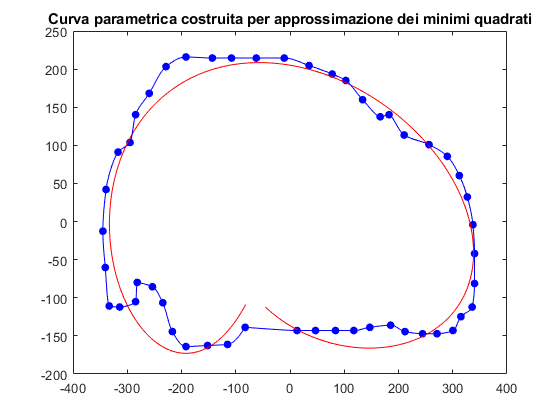

miafotoAppr5=[polinomioA;polinomioB];
plot(xcentrati,ycentrati,'b.', polinomioA,polinomioB,'r','markersize',20,'LineWidth',0.5)
hold on
plot(ascisseSplineH,ordinateSplineH,'b','MarkerSize',0.5)
title('Curva parametrica costruita per approssimazione dei minimi quadrati')
hold off